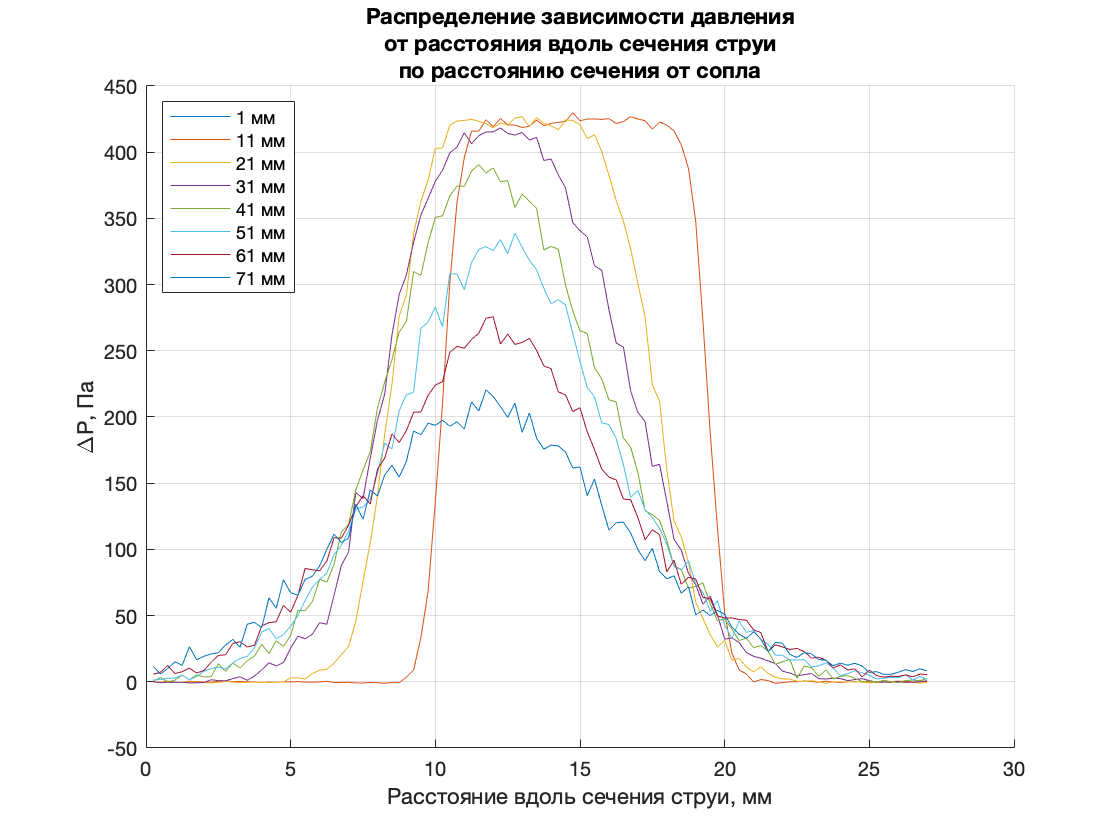

mm01 = load('01mm.dat');
mm11 = load('11mm.dat');
mm21 = load('21mm.dat');
mm31 = load('31mm.dat');
mm41 = load('41mm.dat');
mm51 = load('51mm.dat');
mm61 = load('61mm.dat');
mm71 = load('71mm.dat');

calibzero0 = load('calibzero.dat');
calib0 = load('calib.dat');
calibzero = (calibzero0(:,2))';
calib = (calib0(:,2))';
no_null = ones(size(calib)).*67.1;
null = zeros(size(calibzero));
temp_1 = [calibzero calib];
temp_2 = [null no_null];
t = polyfit(temp_1, temp_2, 1);
dx = 0.25;
x = mm01(:,1)'.*dx;

p01 = polyval(t, mm11(:, 2)');
p11 = polyval(t, mm11(:, 2)');
p21 = polyval(t, mm21(:, 2)');
p31 = polyval(t, mm31(:, 2)');
p41 = polyval(t, mm41(:, 2)');
p51 = polyval(t, mm51(:, 2)');
p61 = polyval(t, mm61(:, 2)');
p71 = polyval(t, mm71(:, 2)');

pressure = [p01; p11; p21; p31; p41; p51; p61; p71];
Names = {'1 мм', '11 мм', '21 мм', '31 мм', '41 мм', '51 мм', '61 мм', '71 мм'};

f = figure;
figure(f);
hold on;
grid on;
title({'Распределение зависимости давления', 'от расстояния вдоль сечения струи', 'по расстоянию сечения от сопла'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

for i = 1:size(pressure, 1)
    plot(x, pressure(i,:),'DisplayName', Names{i});
end

legend('Location',"northwest");

saveas(f, 'pressure.png');